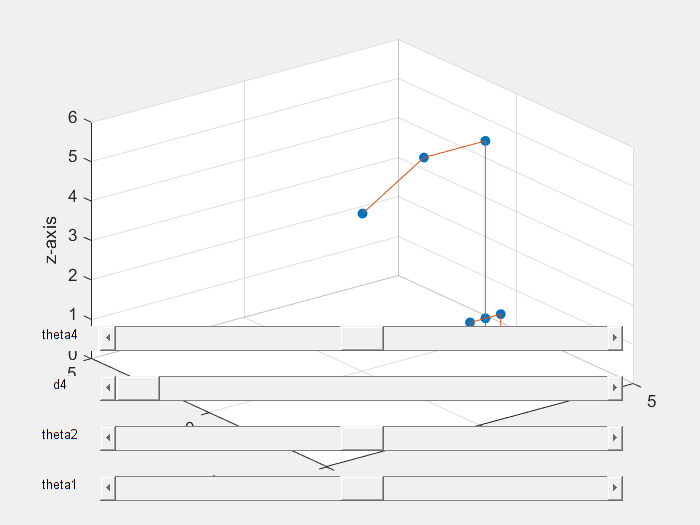

Robot_Simulator

function Robot_Simulator()

    % Create figure and axes
    f = figure;
    ax = axes('Parent', f, 'XLim', [-5, 5], 'YLim', [-5, 5], 'ZLim', [0, 6]);
    xlabel(ax, 'x-axis');
    ylabel(ax, 'y-axis');
    zlabel(ax, 'z-axis');
    view(3);
    grid on;
    hold on;

    % Create sliders
    sld1 = uicontrol('Style', 'slider', 'Min', -180, 'Max', 180, 'Value', 0, 'Position', [81, 20, 419, 20], ...
                     'Callback', @(src, event) updatePlot());
    sld2 = uicontrol('Style', 'slider', 'Min', -180, 'Max', 180, 'Value', 0, 'Position', [81, 60, 419, 20], ...
                     'Callback', @(src, event) updatePlot());
    sld3 = uicontrol('Style', 'slider', 'Min', 0, 'Max', 6, 'Value', 0, 'Position', [81, 100, 419, 20], ...
                     'Callback', @(src, event) updatePlot());
    sld4 = uicontrol('Style', 'slider', 'Min', -180, 'Max', 180, 'Value', 0, 'Position', [81, 140, 419, 20], ...
                     'Callback', @(src, event) updatePlot());

    % Create labels for sliders
    uicontrol('Style', 'text', 'Position', [20, 20, 60, 20], 'String', 'theta1');
    uicontrol('Style', 'text', 'Position', [20, 60, 60, 20], 'String', 'theta2');
    uicontrol('Style', 'text', 'Position', [20, 100, 60, 20], 'String', 'd4');
    uicontrol('Style', 'text', 'Position', [20, 140, 60, 20], 'String', 'theta4');

    % Initial plot
    updatePlot();

    function updatePlot()
        % Get slider values
        theta1 = get(sld1, 'Value');
        theta2 = get(sld2, 'Value');
        d4 = get(sld3, 'Value');
        theta4 = get(sld4, 'Value');
        
        % Convert from degrees to radians
        q1 = deg2rad(theta1);
        q2 = deg2rad(theta2);
        q4 = deg2rad(theta4);

        % Define robot geometry
        V1 = 4;
        V2 = 1;
        A1 = 2;
        A2 = 2;

        % Define transformation matrices
        J1 = [cos(q1), -sin(q1), 0, 0;
              sin(q1), cos(q1), 0, 0;
              0, 0, 1, V1;
              0, 0, 0, 1];
          
        J2 = [cos(q2), -sin(q2), 0, A1;
              sin(q2), cos(q2), 0, 0;
              0, 0, 1, V2;
              0, 0, 0, 1];
          
        J3 = [1, 0, 0, A2;
              0, 1, 0, 0;
              0, 0, 1, 0;
              0, 0, 0, 1];
          
        J4 = [cos(q4), -sin(q4), 0, 0;
              sin(q4), cos(q4), 0, 0;
              0, 0, 1, d4 - V1 - V2;
              0, 0, 0, 1];
          
        % Make the rigid end effector
        p = [-0.5, 0, 0, 1; -0.5, 0, 0.5, 1; 0.5, 0, 0.5, 1; 0.5, 0, 0, 1; 0.5, 0, 0.5, 1; 0, 0, 0.5, 1; 0, 0, V1 + V2, 1]';

        % Propagate and add joint points through the simulation
        p = J4 * [p, [0; 0; 0; 1]];
        p = J3 * [p, [0; 0; 0; 1]];
        p = J2 * [p, [0; 0; 0; 1]];
        p = J1 * [p, [0; 0; 0; 1]];

        % Clear the axes and plot the new points
        cla(ax);
        scatter3(ax, p(1,:), p(2,:), p(3,:), 'filled');
        line(ax, p(1,:), p(2,:), p(3,:));
    end
end
